## Construction of phasor Array

## Intro

The phasorArray class is a usefull tool to manipulate 3D array representing Periodic matrix, storing complex phasor along the third dimension. Obligatory, third dimension must me an odd number. 

Let's use the class PhasorArray to attach usefull function to a 3D matrix representing a periodic matrix and its phasor.

Consider A a 3D array of size $2h+1$ , A(:,:,h+1) is the 0-phasor of A, $A(:,:,(h+1)-m)$ and $A(:,:,(h+1)+m)$ are the $-m$ and $m$ phaors of A. 

The class allow construction, manipulation, edition of phasor in a smooth manner, and redifine all the basic operation (addition, substraction, multiplication, left/right inversion, transposition, conj transpore, real, imag ....) to apply to the periodic matrix instead of the array operation. 

### Construting a phasorArray

#### From fourier coefficient : Construct A a 3D table, from phasor -2 to 2, use PhasorArray to create the object.

A_0=eye(2);
A_1=[1 1i;-1i,2];
A_2=[2*1i, exp(1i*1.89)/4; 0.5, -1];

A_ar=cat(3,conj(A_2),conj(A_1),A_0,A_1,A_2);
A=PhasorArray(A_ar)

Alternatively, specify that A represent a real valued periodic matrix, ie negative phasor are the conjugate of positive phasor, and feed the function only with the Zero and Positive part, and speficify the argument 'z_pospart' to true

A_arpos=cat(3,A_0,A_1,A_2);
A=PhasorArray(A_arpos,'z_pospart',true)

The last way to construct PhasorArray is to specifiy individual periodic coefficient.

For that you can avoid the hassle to construct a 3D matrix, and provide a vector in order to define a scalar periodic PhasorArray. Using this, individual coeef can have different number of phasor but can still concatenate

a_11=ScalarPhasorArray([1,1,2*1i],'z_pospart',true)
a_12=ScalarPhasorArray([0,1i,exp(1i*1.89)/4, 1/7, 1/8*1i ],'z_pospart',true)
a_21=ScalarPhasorArray([0,-1i,0.5],'z_pospart',true)
a_22=ScalarPhasorArray([1,2,-1],'z_pospart',true)

A=[a_11,a_12;a_21,a_22]

#### From a time signal : use inverse FFT to deduce correct Fourier decomposition and build the phasorArray object

T=2
sig = @(t) sawtooth(t/T*2*pi,0.5)
figure
plot(0:1e-3:4,sig(0:1e-3:4))


choose an appropriate **power of 2**

dt = 1/2^4;
t=(0:dt:(1-dt))*T;

y = sig(t);

Use the time2phasor method with a signal sample from 0 to T-dt on 2^m points

Y=PhasorArray.time2Phasor(y,"timeDim",2)
hold on 
plot(Y,T,0:1e-3:4,linetype='-.')
sgtitle('y(t) vs Y->y')

YY = PhasorArray.funcToPhasorArray(sig,T);
hold on 
plot(YY,T)
legend('y','y->Y->y','sig->Y->y')

### Display phasorArray

Display the 3D table inside, ie the fourier coeeficients

%display the 3D array
A.value

Display a stem plot of fourier coefficients, either showing real part, imag part, both, or abs. Default is an explosed view, one subplot for each coeeficient of A(t)

%stem plot
figure
clf
stem(A,display="real",scale="linear")
sgtitle('Stem of real part of Phasor of A')

figure
clf
stem(A,display="imag",scale="linear")
sgtitle('Stem of imag part of Phasor of A')

figure
clf
stem(A,display="abs",scale="linear")
sgtitle('Stem of abs value of Phasor of A')

Plot a time domain realisation of A(t) on a given time vector, for a given period T

%temporal plot
figure
clf
tt=0:0.001:4;
T=2;
plot(A,T,tt,"title",'A(t)')

Alternatively to stem, plot the abs value of phasor in a 3D bar chart, beware, as the matrix is first vectorized one direction

figure
barsurf(A)

The explosed option of stem can be disabled, resulting in a superposition of the different harmonics

figure
stem(A,"explosed",0,"scale","linear")

### Perform derivation and phase shift

figure
plot(d(A,2),2,0:0.001:4,"title","A(t)'") %derivative of A, for a period T=2

figure
plot(dephase(A,pi/2),2,0:0.001:4,"title","A(t+T/4)") %dephasage de A de pi/2 rad

### Edit PhasorArray

You can modify value of PhasorArray by two means

Access 3D array using parenthesis to manipulate it as a 3D array in regular matlab way

A(1,1,3)=5 % access the third page of 3D array, since A is of size 5,
% the 3rd page is the central page,
% so it is the 0 phasor,
%  since we specify (1,1,3) we edit the value of the first coeeficient of
%  A(t)

A(1,1,(A.h+1)+0) = 5 %A.h produces the number of phasor in A
% so (A.h+1)+k is the index of the k-th phasor page

Alternatively **use bracket with 2 indices** to access coefficient subphasor array, you can use bracket indexing to totaly replace phasor value of specified coefficients

A{1,1} %extract the phasor Array of (1,1) element of A(t)
figure
plot(A)


figure
plot(A{1,1})

A{1,1}=9;
hold on
plot(A{1,1})

A{1,1}=ScalarPhasorArray([5 1/2*1i],'z_pospart',true); %replace a_11 with 5-sin(wt)
hold on
plot(A{1,1})

You can also **use bracket with 3 indices **to assign to specific phasor BUT unlike parenthesis indexing the third argument is a phasor indices 

- A{1,2,3} access the third phasor of $a_{12}$ in the same way A(1,1,3+1+A.h) does

- A{1,1,-3} is a licit indexing

- if k is too big (k > A.h) the output is zero

- It is possible tu assign value with k > A.h

A{1,1,1}
A(1,1,1+1+A.h)
A{1,1:2,7}
A{:,:,-4}

%change value of phasor -3 of a_11 and a_12
A{1,1:2,-3}=[1/4*1i 1/3+1i/5] 

A{1,2,12}=0.1
A{1,2,-12}=0.1

To access full phasor of  order k, an alternative to A{:,:,k} is A.phas(k)

A.phas(-3)

finally use A{:} to extract a vector form of A

A{:}
figure
plot(A{:})

Use trunc et reduce pour réduire les phasor Array

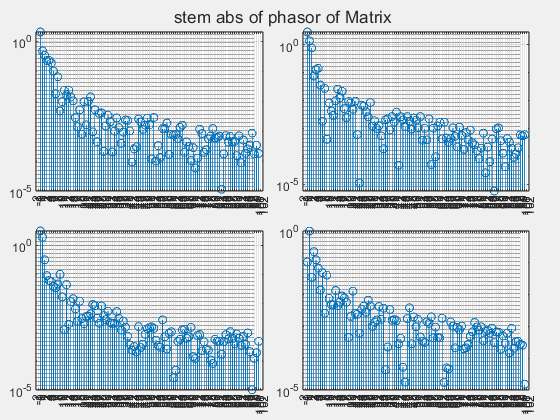

E=rand_phasor(2,2,100,'output','PhasorArray')
figure
stem(E)

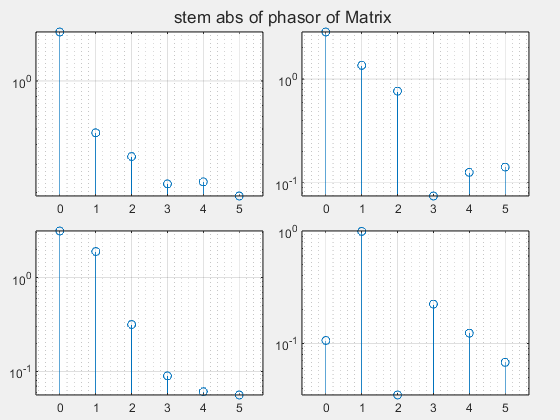


figure
stem(E.trunc(5))


figure
stem(E.reduce('reduceMethod','absolute','reduceThreshold',1e-2))

coupe des que tous les phasors après sont plus petit que 1e-2

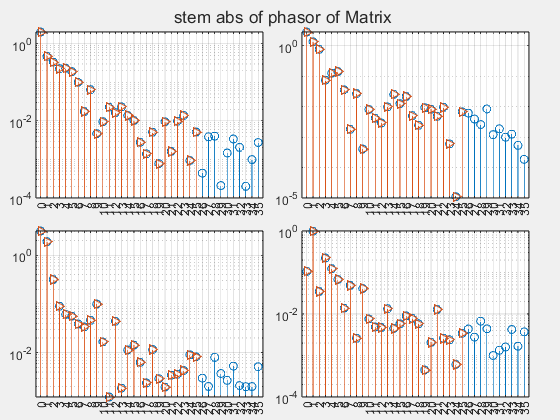


hold on
stem(E.reduce('reduceMethod','relative','reduceThreshold',1e-2),'marker','>')

coupe des que tous les phasors après sont plus petit que 1e-2 fois le max des phasors

### Basic manipulation

We want to manipulate the 3D array (Phasor Array) as is they are matrices. Hence we redefine the + * .* / ./ ' .' operateur to produce result on the periodic matrices. 

A+4 (addition with a scalar) adds 4 only to the 0 phasor, C=A*B realise the product of the periodic matrices st $C(t)=A(t)B(t)$, the is element wise product too : C=A.*B means $c_{kl}(t) = a_{kl}(t) b_{kl}(t)$ and so on for matrix division and element wise division. 

PhasorArray class define the addition in the sens of Matrix : AA=A+4 adds 4 only to the 0 phasor of A 

AA=A+8*eye(2)

AA = 2x2x25 PhasorArray of double representing a 2x2 complex-valued periodic matrix with 12 harmonics

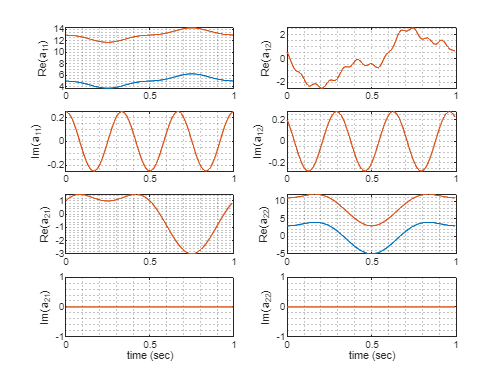

figure
plot(A)
hold on 
plot(AA)

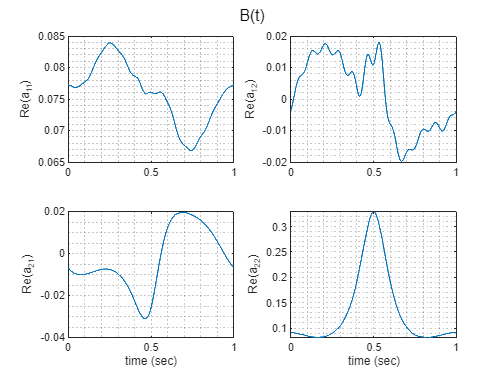

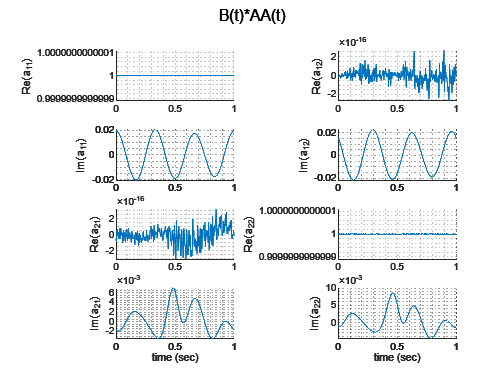



B=1/AA;
figure
plot(B,title='B(t)')
hold on 
plot(B*AA,title='B(t)*AA(t)') 


C=rand_phasor(2,2,5,"output","PhasorArray","time_structure","real")

C = 2x2x11 PhasorArray of double representing a 2x2 real-valued periodic matrix with 5 harmonics

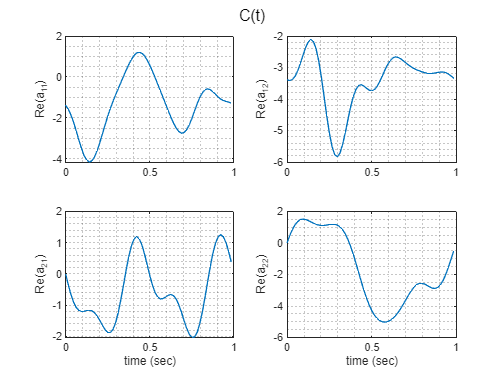

figure
plot(C,title='C(t)')

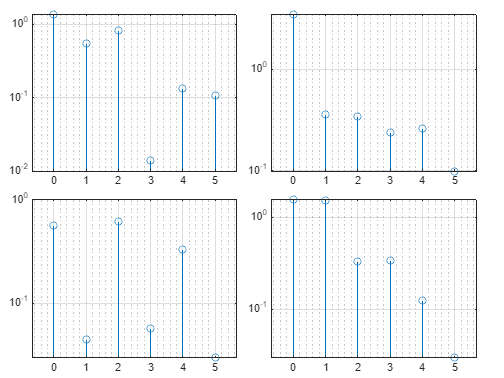

figure
stem(C)

figure
plot(A*C,title='product A(t) \times C(t)')


figure
clf
stem(A*C)
figure
clf
plot(A.') %transpose et complexe transpose fonctionnent
hold on
plot(A)


You can perform smoothly addition and substraction of phasor array containing a different number of phasor as long as the first two dimmension are compatible

D=rand_phasor(2,2,4)
E=A-D

F=kron(A,D)

Basic function such as sum, trace, diag etc are available

diag(A)
figure
plot(diag(A))

trace(A)
figure
plot(trace(A))


N.B. notice that $trace(\mathcal{T}_m(A))=\frac{trace(A(t)_0)}{2m+1}$

Power are defined

figure
plot(A)
figure
plot(A^3)
figure
plot(A.^5)

## Simulation of system

Lets take a random periodic matrix with imposed eigen value on S-N

figure
S=mreal(rand_phasor(2,2,7,"hurwitzeig",[-1 -0.3],"time_structure","hurwitz",output="PhasorArray"))

tmax=15;
T=1
x0=rand(2,1);
[y,t]=lsim(S,tmax,x0,T,"plot",true,"isRealValued",1); 
%isRealValue ensure only real value are used, tune this argument to true if
%the periodic matrices are real valued
title('x(t)')

figure
plot(S{:},T,0:0.01:tmax,title='S(t)')

figure
plot(S.HmqNEig([],T),'*')
title('eig(S-N)')


We now add an input to the simulation

B=PhasorArray.random(2,1,5,"time_structure","real")+3
figure
plot(B,T,0:0.01:tmax)

figure
[y,t]=lsim(S,tmax,x0,T,B,"plot",true,"isRealValued",1);
title('x(t)')


## Advanded manipulation

Take a complexe valued phasor array, you can extract the real part of A(t) and imag part of A(t), conjugate phasor, and transpose conjugate phasor with '

X = rand_phasor(2,2,5,"time_structure","cmplx",output="PhasorArray")
figure
plot(X,1,0:0.01:2,"DispImag",1,"DispReal",1)

rX=mreal(X)
figure
plot(rX,1,0:0.01:2,"DispImag",1,"DispReal",1)

iX=mimag(X)*1i
figure
plot(iX,1,0:0.01:2,"DispImag",1,"DispReal",1)

cX=mconj(X)
figure
plot(cX,1,0:0.01:2,"DispImag",1,"DispReal",1)

tcX=X'
figure
plot(tcX,1,0:0.01:2,"DispImag",1,"DispReal",1)



## Harmonic Array

Construct the Toeplitz Block Form and BlockToeplitz form of order h using the BT and TB method

h=5

%TB and BT matrix
A.TB(h)
A.BT(h)

%en version sparse
A.spBT(h)
A.spTB(h)

T=1 %period
nx=2 %number of state
NTB(nx,h,T)
NBT(nx,h,T)

spNBT(nx,h,T)
spNTB(nx,h,T)
figure
barsurf(A.TB(10),'EdgeColor','interp')
view([0 90.00])


The 'N' function accept a phasorArray as first argument and deduce from the first dimension of the matrix the number of state

NTB(A,h,T)

to compute the square hankel form used in LMI use

 [$\mathcal{H}_{m,m}(A^+)\mathcal{J}_{m,m},\mathcal{J}_{m,m}\mathcal{H}_{m,m}(A^-),\mathcal{H}_{m,m}(A^+),\mathcal{H}_{m,m}(A^-)]=A.TBHankel(h);$

BT hankel is not yet implemented

[HpJ,JHm,Hp,Hm]=A.TBHankel(h);
% [HpJ,JHm,Hp,Hm]=A.BTHankel(h); 

%sparse versions
[HpJ,JHm,Hp,Hm]=A.spTBHankel(h);

compute eigenvalue of A and eigen value of A-N

A.HmqNEig(h,T)
A.HmqEig(h)


Output sincos form, imag real form etc in the form of 3D array

u=ScalarPhasorArray([1 1/2 -1/2/1i],"z_pospart",1)
% u = 1 + cos - sin
figure
plot(u,1,0:0.01:2,title='u')

u.SinCosForm
u.ImagRealForm

## Symbolic and sdpvar

The toolbox allows for definition of symbolic and sdp variable in the form of PhasorArray to perform all the previous operations

hP=5

%liste de sdp var servant aux phaseur 
P2=(sdpvar(size(A,1),size(A,2),hP,'symmetric','complex'))
%sdpvar phaseur 0 (réel)
P1=(ndsdpvar(size(A,1),size(A,2),1,'symmetric','real'))
%sdpvar phaseur array
P = PosPart2PhasorArray(P1,P2)
PT=P.TB(h)

%ou directement avec la methode statique de PhasorArray
P = PhasorArray.ndsdpvar(2,2,5,PhasorType='symmetric',real=true)

P=sdpval(P)
% P = value(value(P))
%to extract the value in P after optim

see LMI example for more details

Also, symbolic phasorArray are available

S = PhasorArray.sym(2,2,5,'s')
S.TB(3)
S.TBHankel(3)

R = PhasorArray.random(2,2,2)

SymPlusR=TB(S+R,3)
vpa(SymPlusR,3)
SymTimesR=TB(S*R,3)
vpa(SymTimesR,3)

## Lyapunov and Sylvester eq

A=mreal(rand_phasor(4,4,7,"hurwitzeig",[-1 -0.7 -0.1 -0.3],"time_structure","hurwitz",output="PhasorArray"))
Q=PhasorArray(eye(4));

hp=10;
T0=1;

%A^TP + PA +Q =0
P=PhasorArray(Sylv_harmonique(A',A,Q,2*hp,2*pi/T0));
figure
plot(P)

nx=size(A,1)
nz=2

C=PhasorArray(rand_phasor(nz,nx,4,"time_structure","real"))
O=rand(nz,nz)

%-OM + MA -C =0
M=PhasorArray(Sylv_harmonique(-O,A,-C,2*hp,2*pi/T0));
plot(M)


## More...


% les formes fourier au lieu de Toepliz
S.TF_BT
S.TF_TB 


%forme Fourier vec en TB
S.FvTB(h)
S{:}.TF_BT

%TB2Array converti une matrice TB, dont on connait le nombre de bloc, pour
%en reconstruite le phasorArray 3D
TB2array(A.TB(h),size(A,1)) 


sum(A,1)
permute(A,[2 1])
size(A,1)
size(A,2)
numel(A)
numelt(A)

angle=1.57 %rad
evalp(A,angle)

B=rand_phasor(3,1,7,'output','PhasorArray')
iscolumn(B)
isrow(B)
isrow(B.')
ismatrix(B)
issquare(B)

C=rand_phasor(1,1,8,'output','PhasorArray')
isscalar(C)

issquare(A)

figure
plot(A)
figure
plot(retro(A))
